load("speechCommandModelv5.mat")

% Now taking own voice recording and predicting\
disp("Start speaking")

Start speaking


recObj = audiorecorder(16000,16,1);
recordblocking(recObj,1);
disp("Recording finished")

Recording finished


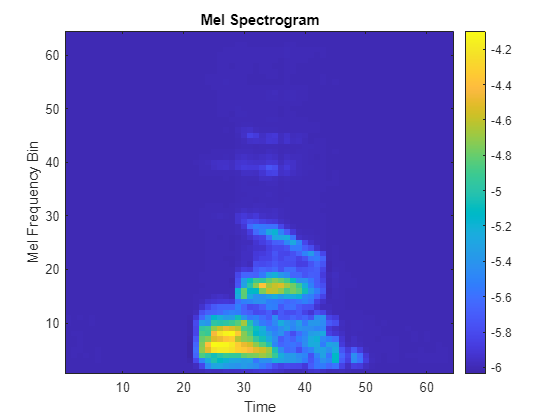


audio = getaudiodata(recObj);
audiowrite("testRecording.wav",audio,16000);

fs = 16000;
%audio = audio ./ (max(abs(audio)) + 1e-6);

%sound(audio,fs)

melSpec = melSpectrogram(audio, fs, 'NumBands',64);
melSpec = log10(melSpec + 1e-6);
melSpec = imresize(melSpec,[64 64]);
inputImage = reshape(melSpec,[64 64 1 1]);

figure;
imagesc(melSpec);
axis xy;
xlabel("Time");
ylabel("Mel Frequency Bin");
title("Mel Spectrogram");
colorbar;


[predictedWord, scores] = classify(net,inputImage);

disp("First Guess: ");

First Guess: 


disp(predictedWord)

     no 




%sets confidence threshold so that if its <75% confident it will just
%classify it as unknown
threshold = 0.75;
maxScore = max(scores);
fprintf("Confidence: %.1f%%\n", maxScore*100);

Confidence: 99.6%



if maxScore < threshold
    predictedWord = categorical("unknown");
end

disp("Predicted word: ");

Predicted word: 


disp(predictedWord)

     no 

